# Post processing

## Load files

% clear workspace
clear
clc
close all

FINAL_T = 3.0;

% define useful quantites for later-use
t = [0.1:0.1:FINAL_T];
x_shape = zeros(length(t),280)./0;
y_shape = zeros(length(t),280)./0;
circularity = zeros(1,length(t));

% laod file
load log_file.txt

% Set options to read the file
opt = {'Delimiter',' '};
fmt = repmat('%f',1,5);
coor = {};

% Read the file, skipping characters
fid = fopen('interface.txt','rt');
k=1;
while ~feof(fid)
    str = fgetl(fid);
    if strncmp('=====================',str,7)
		% Append data ridden
        coor{end+1} = textscan(fid,fmt,opt{:});

		% Count the number of outputs
		l(k)=length(coor{1,end}{1,end});

		% Save the coordinates
		x_shape(k,1:l(k)) = coor{1,end}{1,1};
		y_shape(k,1:l(k)) = coor{1,end}{1,2};

		% Increment k
		k=k+1;
    end
end
fclose(fid);

## Generate simulation video

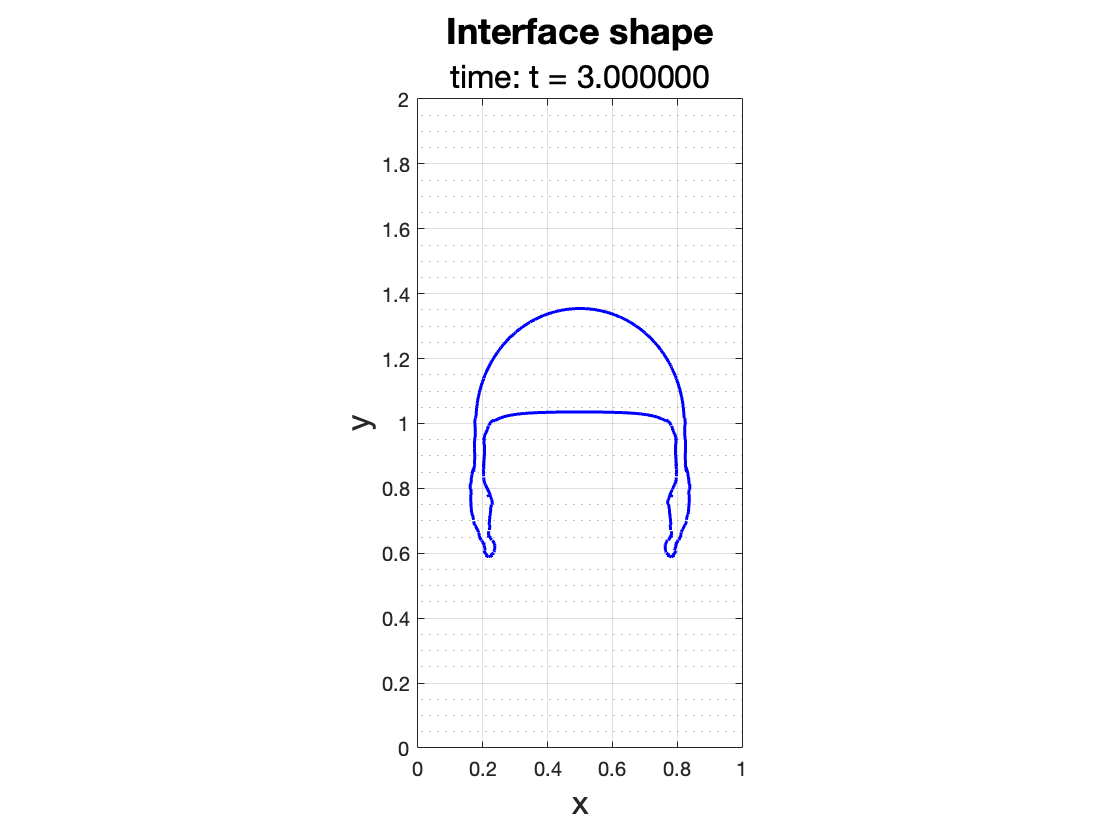

figure();

% Symmetrize
y_rev = y_shape.*-1;

% Compute the number of segment to be plotted
nSegments = size(y_shape(1,:),2)/2;

%% Initialize video
myVideo = VideoWriter('video', 'MPEG-4'); %open video file
myVideo.FrameRate = 10;  %can adjust this, 5 - 10 works well for me
open(myVideo)

for i=1:length(t)
	% plot each segment
	for j=1:nSegments
		plot(y_shape(i,2*(j-1)+1:2*j) + 0.5, x_shape(i,2*(j-1)+1:2*j), 'b-', LineWidth=1.5)
	    hold on
		plot(y_rev(i,2*(j-1)+1:2*j) + 0.5, x_shape(i,2*(j-1)+1:2*j), 'b-', LineWidth=1.5)
	end
	% video properties
	title("Interface shape", 'FontSize', 18);
	subtitle(['time: t = ' num2str(t(i), '%f')], 'FontSize', 16);
	axis equal
	xlabel('x', 'FontSize', 16); ylabel('y', 'FontSize', 16);
	grid on
	set(gca,'XMinorGrid','off','YMinorGrid','on')
	axis([0 1 0 2])
	set(gca,'xtick',[0:0.2:1])
	% print a preview
	if t(i) == 0.1
		saveas(gcf,['video_preview.png'])
	end
	hold off
	% pause for the real time simulated
	pause(0.1);
	% get the frame for video generation
	frame = getframe(gcf);
	% create the video
    writeVideo(myVideo, frame);
end

close(myVideo)

## Load output files with field data

% outer fluid
output_field_name = [];
output_field = {};
x = {}; y = {};
ux = {}; uy = {};
vort = {};
p = {};

for i = 1:length(t)
	output_field_name = [ output_field_name; ['output_field-' num2str(t(i), '%2.1f') '.txt']];
	output_field{i,1} = load(output_field_name(i,:));
end

% Load files in a handy way
% Format:
% x, y, u.x[], u.y[], p[], vort[]
for i = 1:length(t)
	x{i,1} = [output_field{i,1}(:,2)+0.5; -output_field{i,1}(:,2)+0.5];
	y{i,1} = [output_field{i,1}(:,1); output_field{i,1}(:,1)];
	ux{i,1} = [output_field{i,1}(:,4); -output_field{i,1}(:,4)];
	uy{i,1} = [output_field{i,1}(:,3); output_field{i,1}(:,3)];
	p{i,1} = [output_field{i,1}(:,5); output_field{i,1}(:,5)];
	vort{i,1} = [output_field{i,1}(:,6); output_field{i,1}(:,6)];
end

% bolla
output_field_name_b= [];
output_field_b = {};
x_b = {}; y_b = {};
ux_b = {}; uy_b = {};
vort_b = {};
p_b = {};

for i = 1:length(t)
	output_field_name_b = [ output_field_name_b; ['output_field_bolla-' num2str(t(i), '%2.1f') '.txt']];
	output_field_b{i,1} = load(output_field_name_b(i,:));
end

% Load files in a handy way
% Format:
% x, y, u.x[], u.y[], p[], vort[]
for i = 1:length(t)
	x_b{i,1} = [output_field_b{i,1}(:,2)+0.5; -output_field_b{i,1}(:,2)+0.5];
	y_b{i,1} = [output_field_b{i,1}(:,1); output_field_b{i,1}(:,1)];
	ux_b{i,1} = [output_field_b{i,1}(:,4); -output_field_b{i,1}(:,4)];
	uy_b{i,1} = [output_field_b{i,1}(:,3); output_field_b{i,1}(:,3)];
	p_b{i,1} = [output_field_b{i,1}(:,5); output_field_b{i,1}(:,5)];
	vort_b{i,1} = [output_field_b{i,1}(:,6); output_field_b{i,1}(:,6)];
end

## Velocity field

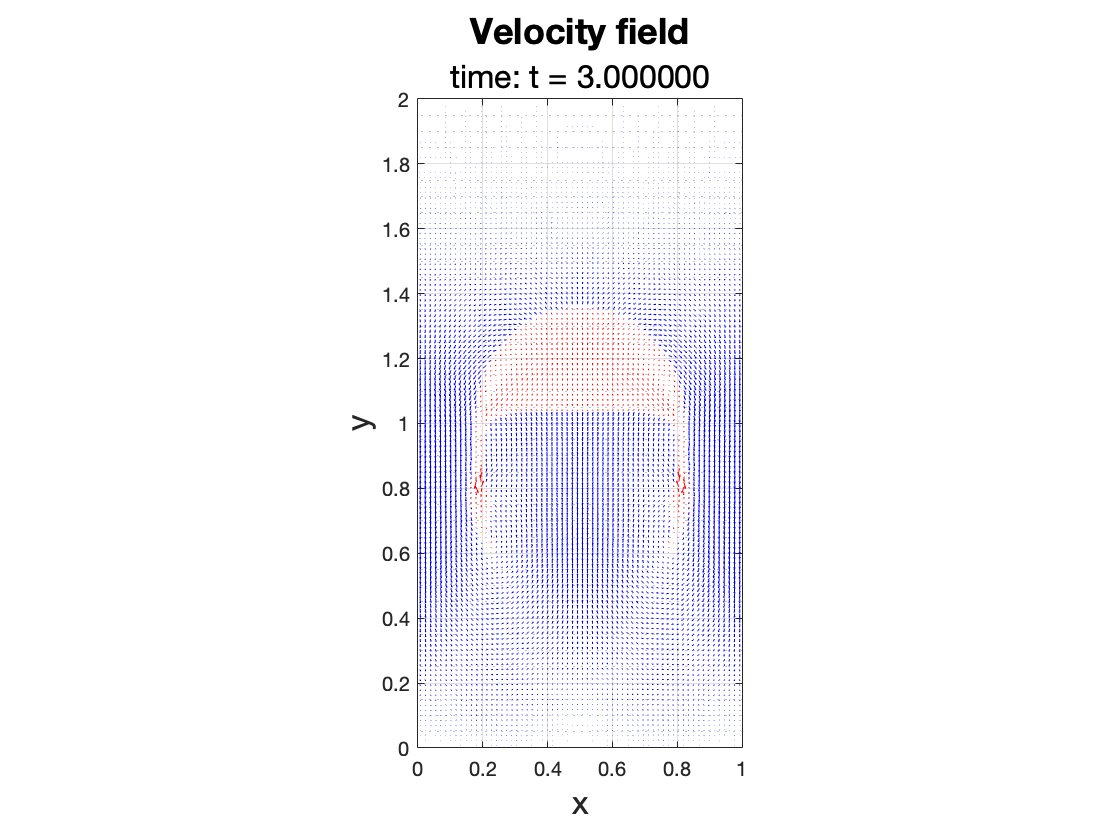

figure();

for i=1:length(t)
	% actual plot
	quiver(x{i,1}, y{i,1}, ux{i,1}, uy{i,1}, 'b');
	% plot properties
	title("Velocity field", 'FontSize', 18);
	subtitle(['time: t = ' num2str(t(i), '%f')], 'FontSize', 16);
	axis equal
	xlabel('x', 'FontSize', 16); ylabel('y', 'FontSize', 16);
	grid on
	set(gca,'XMinorGrid','off','YMinorGrid','on')
	set(gca,'xtick',0:0.2:1)
	axis([0 1 0 2])

	hold on
	quiver(x_b{i,1}, y_b{i,1}, ux_b{i,1}, uy_b{i,1}, 'r');

% ==> save the desired istant
	if t(i) == 3.0
		saveas(gcf,['velocity_field' num2str(t(i), '%f') '.png'])
	end
	hold off
	% pause for the real time simulated
	pause(0.1);
end

## Velocity field - zoom

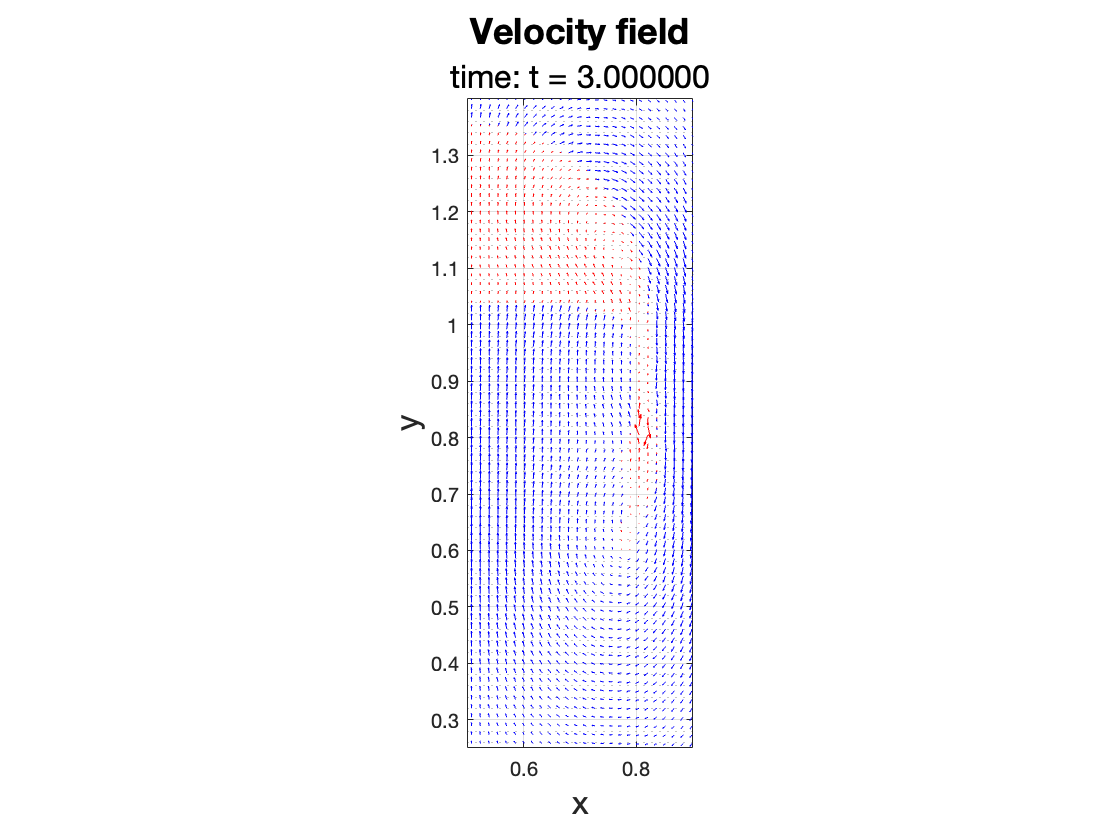

figure();

for i=1:length(t)
	% actual plot
	quiver(x{i,1}, y{i,1}, ux{i,1}, uy{i,1}, 'b');
	% plot properties
	title("Velocity field", 'FontSize', 18);
	subtitle(['time: t = ' num2str(t(i), '%f')], 'FontSize', 16);
	axis equal
	xlabel('x', 'FontSize', 16); ylabel('y', 'FontSize', 16);
	grid on
	set(gca,'XMinorGrid','off','YMinorGrid','on')
	set(gca,'xtick',0:0.2:1)
	xlim([0.5 0.9])
	ylim([0.25 1.4])

	hold on
	quiver(x_b{i,1}, y_b{i,1}, ux_b{i,1}, uy_b{i,1}, 'r');

% ==> save the desired istant
	if t(i) == 3.0
		saveas(gcf,['velocity_field_zoom' num2str(t(i), '%f') '.png'])
	end
	hold off
	% pause for the real time simulated
	pause(0.1);
end

## Velocity field

figure();
streamline(ux{1,1}, uy{1,1});

Error using streamline>parseargs
Wrong number of input
arguments.

Error in streamline (line 51)
[verts, x, y, z, u, v, w, sx, sy, sz, options] = parseargs(nargs,args);

## Sort data

figure();

sorted_data = [x{1,1}'; y{1,1}'; ux{1,1}'; uy{1,1}'; p{1}'; vort{1}']';
sorted_data = sorted_data(sorted_data, 2);
y_ref = sorted_data(1,:);
i = 1; k = 1;


% uniform grid
xi = linspace(0.0, 1.0);                              % Interpolation Grids
yi = linspace(0.0, 2.0);
[Xi,Yi] = meshgrid(xi, yi);
% z-values
surf(Xi, Yi, Zi)

for i=1:length(t)
	% vorticity
	plot(x{i,1}, y{i,1}, vort{i,1}, '.');
	hold on
	plot(x_b{i,1}, y_b{i,1}, vort_b{i,1}, '.');

	% plot properties
	title("Velocity field", 'FontSize', 18);
	subtitle(['time: t = ' num2str(t(i), '%f')], 'FontSize', 16);
	axis equal
	xlabel('x', 'FontSize', 16); ylabel('y', 'FontSize', 16);
	grid on
	set(gca,'XMinorGrid','off','YMinorGrid','on')
	set(gca,'xtick',0:0.2:1)
	axis([0 1 0 2])

% ==> save the desired istant
	if t(i) == 3.0
		saveas(gcf,['velocity_field' num2str(t(i), '%f') '.png'])
	end
	hold off
	% pause for the real time simulated
	pause(0.1);
end

## Compute circularity

Pb = zeros(1,length(t));

for i=1:length(t)

	tmp_x = x_shape(i,:);
	tmp_y = y_shape(i,:);
	tmp_x(isnan(tmp_x)) = 0;
	tmp_y(isnan(tmp_y)) = 0;

	tmp_v = [tmp_y+0.5; tmp_x]';

	% compute perimeter
	for j=1:nSegments-1
		Pb(1,i) = Pb(1,i) + 2*sqrt( (tmp_x(j)-tmp_x(j+1))^2 + (tmp_y(j) - tmp_y(j+1) )^2 );
	end

	[k,A]= boundary(tmp_x',tmp_y');

	circularity(i) = sqrt(A*1.7 * 4 / pi) * pi / (Pb(i)*1.7513);
end

## Bubble shape comparison

% load c2g1l4s.txt  % TU Dortmund (TP2D)
%load c2g2l1s.txt  % EPFL Lausanne (FreeLIFE)
% load c2g3l4s.txt  % Uni Magdebug (MooNMD)
load log_file.txt % ours

% data1 = c2g1l4s;
% data2 = c2g2l1s;
% data3 = c2g3l4s;

close all

% plot(data1(1:2,1),data1(1:2,2), 'k:', LineWidth=1.5)
hold on
% plot(data2(1:2,1),data2(1:2,2), 'r:', LineWidth=1.5)
% plot(data3(1:2,1),data3(1:2,2), 'b:', LineWidth=1.5)
plot(y_shape(1,1:2) + 0.5, x_shape(1,1:2), '-', LineWidth=2)

% nSegments = size(data1,1)/2;
% for i=1:nSegments
%   plot(data1(2*(i-1)+1:2*i,1),data1(2*(i-1)+1:2*i,2), 'k:', LineWidth=1.5)
% end
% nSegments = size(data2,1)/2;
% for i=1:nSegments
%   plot(data2(2*(i-1)+1:2*i,1),data2(2*(i-1)+1:2*i,2), 'r:', LineWidth=1.5)
% end
% nSegments = size(data3,1)/2;
% for i=1:nSegments
%   plot(data3(2*(i-1)+1:2*i,1),data3(2*(i-1)+1:2*i,2), 'b:', LineWidth=1.5)
% end
grid on
set(gca,'xtick',linspace(0.5,1,2^8))
set(gca,'ytick',linspace(0.75,1,2^8))
nSegments = size(y_shape,2)/2;
for j=1:nSegments
	plot(y_rev(end,2*(j-1)+1:2*j) + 0.5, x_shape(end,2*(j-1)+1:2*j),'-', 'color',[0.4940, 0.1840, 0.5560], LineWidth=2)
	plot(    y_shape(end,2*(j-1)+1:2*j) + 0.5, x_shape(end,2*(j-1)+1:2*j),'-', 'color',[0.4940, 0.1840, 0.5560], LineWidth=2)
end
hold off
axis equal
% axis([-0 1 0 2])
xlim([0 1])
ylim([0 2])
xlabel('x', 'FontSize', 16); ylabel('y', 'FontSize', 16);
title("Bubble shape", 'FontSize', 18);
subtitle("time t = 3.0", 'FontSize', 16);
set(gca,'ytick',[0: 0.2: 2],'FontSize', 16)
set(gca,'xtick',[0: 0.2: 1],'FontSize', 16)
legend("TU Dortmund (TP2D)", "EPFL Lausanne (FreeLIFE)", "Uni Magdebug (MooNMD)", "Our results", 'location', 'northeastoutside', 'FontSize', 16)

## Circularity comparison

% load c2g1l4.txt  % TU Dortmund (TP2D)
% load c2g2l1.txt  % EPFL Lausanne (FreeLIFE)
% load c2g3l4.txt  % Uni Magdebug (MooNMD)

figure();
plot(c2g1l4(:,1),c2g1l4(:,3), 'k:', 'LineWidth', 1.5)
hold on
plot(c2g2l1(:,1),c2g2l1(:,3), 'r:', 'LineWidth', 1.5)
plot(c2g3l4(:,1),c2g3l4(:,3), 'b:', 'LineWidth', 1.5)
plot(t-0.1, circularity(1,:), '-', 'LineWidth', 2)
hold off
title('Bubble - circularity', 'FontSize', 16)
xlabel('Time', 'FontSize', 14)
ylabel('y', 'FontSize', 14)
xlim([0 3])
legend("TU Dortmund (TP2D)", "EPFL Lausanne (FreeLIFE)", "Uni Magdebug (MooNMD)", "Our results", 'location', 'southwest', 'FontSize', 14)
grid on

figure();
plot(c2g1l4(:,1),c2g1l4(:,4), 'k:', 'LineWidth', 1.5)
hold on
plot(c2g2l1(:,1),c2g2l1(:,4), 'r:', 'LineWidth', 1.5)
plot(c2g3l4(:,1),c2g3l4(:,4), 'b:', 'LineWidth', 1.5)
plot(rising_log_quantities_2(:,1),rising_log_quantities_2(:,2), '-', 'LineWidth', 2)
hold off
title('Bubble - Center of mass', 'FontSize', 16)
xlabel('Time', 'FontSize', 14)
ylabel('y', 'FontSize', 14)
xlim([0 3])
legend("TU Dortmund (TP2D)", "EPFL Lausanne (FreeLIFE)", "Uni Magdebug (MooNMD)", "Our results", 'location', 'southeast', 'FontSize', 14)
grid on

figure();
plot(c2g1l4(:,1),c2g1l4(:,5)*0.9, 'k:', 'LineWidth', 1.5)
hold on
plot(c2g2l1(:,1),c2g2l1(:,5), 'r:', 'LineWidth', 1.5)
plot(c2g3l4(:,1),c2g3l4(:,5), 'b:', 'LineWidth', 1.5)
plot(rising_log_quantities_2(:,1),rising_log_quantities_2(:,3), '-', 'LineWidth', 2)
hold off
title('Bubble - rise velocity', 'FontSize', 16)
xlabel('Time', 'FontSize', 14)
ylabel('y', 'FontSize', 14)
xlim([0 3])
legend("TU Dortmund (TP2D)", "EPFL Lausanne (FreeLIFE)", "Uni Magdebug (MooNMD)", "Our results", 'location', 'best', 'FontSize', 14)
grid on


## colors

newcolors = [
252, 15, 192
192, 32, 208
132, 50, 223
71, 67, 239
11, 84, 254]/256;
colororder(newcolors)


[X,Y] = meshgrid(-5:.5:5);
Z = Y.*sin(X) - X.*cos(Y);
s = mesh(X,Y,Z,'FaceAlpha','0.5')
s.FaceColor = 'flat';